A=[11 5 4
    5 25 4
    5 4 10]

A =     11     5     4
     5    25     4
     5     4    10


x0=[1 1 1]'

x0 =      1
     1
     1


b=[10;10;10]

b =     10
    10
    10


[E,s, T] = MatJacobiSeid(x0,A,b,5e-5,100,1)

s =     0.5988
    0.1796
    0.6287


es una aproximación de la solución del sistmea con una tolerancia= 0.000050

E =     1.0500    0.5849    0.1432    0.0214    0.0020    0.0004    0.0002    0.0000


s =     0.5988
    0.1796
    0.6287


T =          0   -0.4545   -0.3636
         0    0.0909   -0.0873
         0    0.1909    0.2167


x1=[25 29 31]

x1 =     25    29    31


y=s

y =     0.5988
    0.1796
    0.6287


d=2

d = 2

[tabla] = Spline(x1,y,d)

tabla =     0.0000   -0.1048    3.2186
    0.1647   -9.6556  141.7059


syms x

p1=tabla(1,2)*x+tabla(1,3)

$$p1 = \frac{7247591340030965}{2251799813685248}-\frac{7550976602609915\,x}{72057594037927936}$$

p2=tabla(2,1)*x^2+tabla(2,2)*x+tabla(2,3)

$$p2 = \frac{5932856420969463\,x^{2}}{36028797018963968}-\frac{2717821568105729\,x}{281474976710656}+\frac{623229212826639}{4398046511104}$$


fplot(p1,[25 29])
hold on
fplot(p2,[29 31])
hold on
sol=double(subs(p1,x,27))

sol = 0.3892

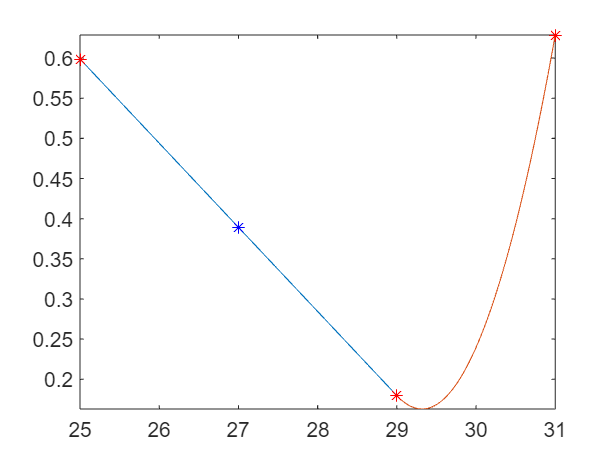

scatter(x1,y,'r*')
hold on
plot(27,sol,'b*')

hold off

x=[0 1 2];
y=[1 3 0];
[pol] = Lagrange(x,y);
polinomio_str = lagrangePolinomio(pol)

polinomio_str = '(x/2 - 1/2)*(x - 2) - (((5*x)/2 - 5)*(x - 3))/2 - ((9*x)/2 - 9/2)*(x - 3)'

sol=str2sym(polinomio_str)

$$sol = \left(\frac{x}{2}-\frac{1}{2}\right)\,\left(x-2\right)-\frac{\left(\frac{5\,x}{2}-5\right)\,\left(x-3\right)}{2}-\left(\frac{9\,x}{2}-\frac{9}{2}\right)\,\left(x-3\right)$$

syms x
double(subs(sol,x,1))

ans = -2.5000

  function polinomio_str = lagrangePolinomio(coeficientes)
    n = length(coeficientes) - 1;  % El grado del polinomio
    
    syms x;  % Definir la variable simbólica x
    
    % Inicializar el polinomio
    polinomio = 0;
    
    % Construir el polinomio de Lagrange
    for i = 1:n+1
        termino = coeficientes(i);
        for j = 1:n+1
            if j ~= i
                termino = termino * (x - j) / (i - j);
            end
        end
        polinomio = polinomio + termino;
    end
    
    % Convertir el polinomio a cadena de caracteres
    polinomio_str = char(polinomio);
end
